# Задание №8. Метод Фурье в задачах обработки сигналов. Создаем и обрабатываем аккорд в MATLAB

**1.Случайный выбор основного тона аккорда.** Выполнить случайный выбор первой ноты аккорда с помощью датчика целых чисел

freq = [261.63 293.66 329.63 349.23 392 440 493.88];
syms C D E F G A H;
sfreq = [C D E F G A H];
p = randi(7);
fprintf("Аккорд будет построен от ноты %c малой октавы\nс частотой %f\n", sfreq(p), freq(p));

Аккорд будет построен от ноты C малой октавы
с частотой 261.630000


**2. Получение массива данных для аккорда**. Построить вектор частот для мажорного и минорного аккордов, у которых выбранная нота будет  первой ступенью, основным тоном.  Учесть, что в мажорном аккорде интервалы между ступенями: 4 и 3 полутона;  в минорном аккорде интервалы: 3 и 4 полутона.  Математическая формула пересчета на  i  полутонов от основной частоты f0

.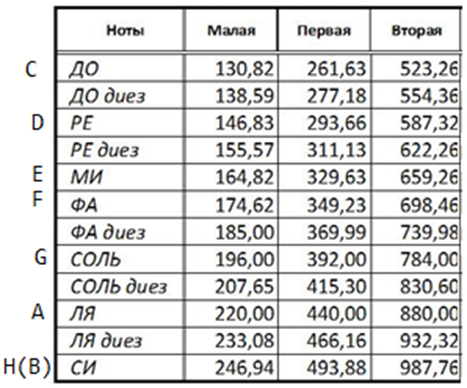

% --Построение для мажорного аккорда--
f2d = freq(p)*2^(4/12)

f2d = 329.6331

f3 = freq(p)*2^(7/12)

f3 = 392.0021

f2m = freq(p)*2^(3/12);
fd = [freq(p); f2d; f3];
fm = [freq(p); f2m; f3];

**3.Построение графиков, озвучка и запись в файл данных** . Составить аккорд, округляя значения частот до целых. Прослушать его, задавая частоту дискретизации   Гц.  Вывести, используя subplot(2,1,i), 2 графика: отдельные гармоники и суммарный сигнал. Записать массив данных аккорда в отдельный файл с расширением  .mat в текущую рабочую папку. 

 ( Ваш файл будет предложен для fft-преобразования другому студенту, который должен будет **на зачете ** проанализировать его с помощью fft,  *расшифровать* закодированный в нем аккорд, *озвучить* весь аккорд и его составляющие по отдельности, *построить график* аккорда и график его составляющих в одном поле, используя subplot(4,1,i), i=1:4.

Поскольку каждому предстоит угадывать чужой аккорд, то следует сначала отработать последовательность действий на своем файле.)

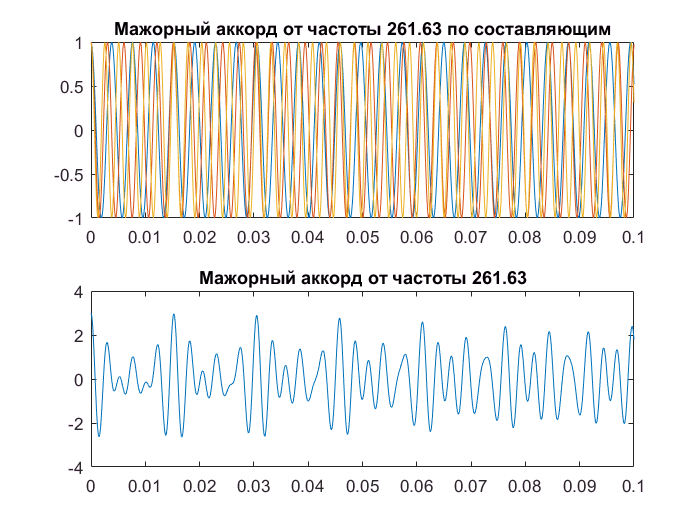

fs = 8000;    %Частота дискретизации
dt = 1/fs;
t = 0:dt:0.1;
yd = cos(2.*pi.*fd.*t);
ym = cos(2.*pi.*fm.*t);
zd = sum(yd);
zm = sum(ym);
figure;
subplot(2, 1, 1);
plot(t, yd);
tt = "Мажорный аккорд от частоты " + num2str(freq(p))+ " по составляющим";
ttt = "Мажорный аккорд от частоты " + num2str(freq(p));
title(tt);
subplot(2, 1, 2);
plot(t, zd);
title(ttt);

Achord1 = repmat(zd, 1, 10);
Achord2 = repmat(zm, 1, 10);
sound(Achord1, fs);
pause(2);
sound(Achord2, fs);
pause(2);

**4. Обработка массива данных с ****fft****.** Загрузить из текущей папки файл с данными об аккорде, имеющий расширение .mat. Выполнить  быстрое преобразование Фурье (fft) и выделить только одну (среднюю) гармонику из спектра, для нее осуществить обратное преобразование Фурье (ifft). Прослушать полученный тон и сравнить его с имеющимся оригинальным тоном. 

Для мажорного аккорда рассмотреть 2 случая: 

а) ifft, выполнено по половинному спектру

б) ifft, выполнено по целому спектру.

Построить графики спектрограммы и сигнала. Увидеть и описать разницу. 

Для минорного аккорда использовать Signal Analyzer, с работой в котором можно познакомиться  на учебном видео: 

Z = fft(zd); % преобразование Фурье от аккорда
L = length(t);
P2 = abs(Z/L);
% --Половинный спектр--
P1 = P2(1:L/2+1);

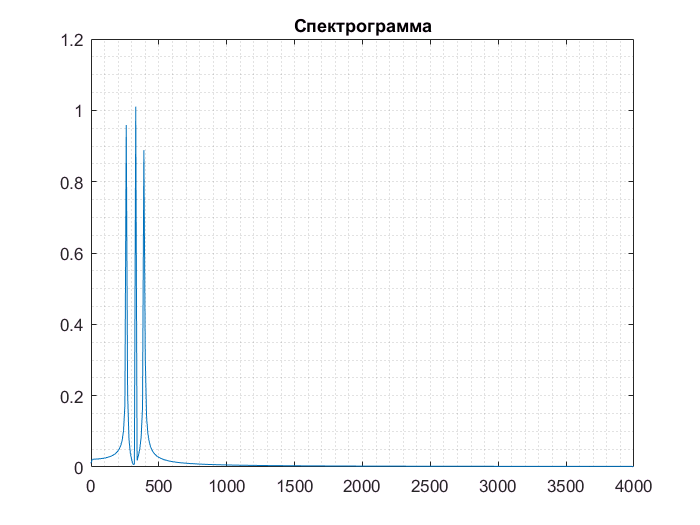

P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:(L/2))/L;
figure;
plot(f,P1);
title('Спектрограмма');
grid minor;

[fmax, x] = max(P1);
for i = 1:length(P1)
    if i ~= x
        P1(i) = 0;
    end
end
z = ifft(P1)*L;
figure;
plot(t(1:length(t)/2 + 1), z);

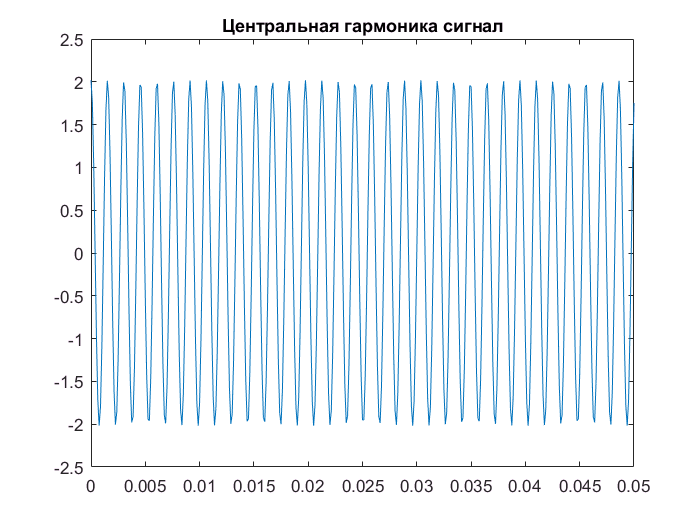

title('Центральная гармоника сигнал');

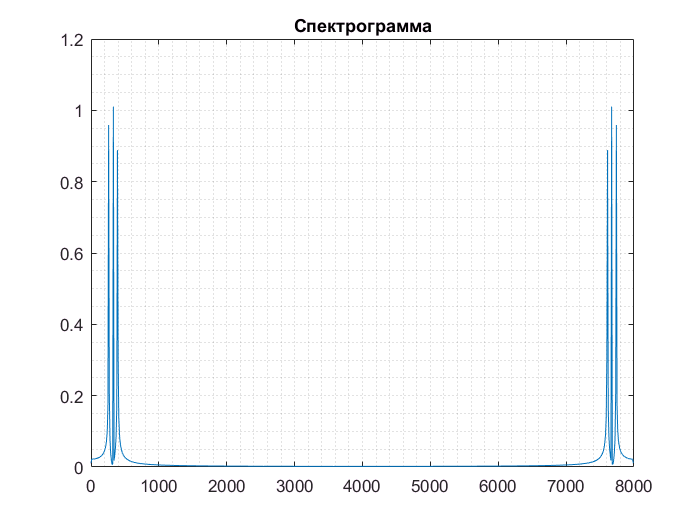

sound(repmat(real(z), 1, 10), fs);
pause(2);

% --Целый спектр--
P2 = abs(Z/L);
P1 = P2(1:L);
P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:L-1)/L;
figure;
plot(f,P1);
title('Спектрограмма');
grid minor;

[fmax, x] = max(P1);
for i = 1:length(P1)
    if i ~= x
        P1(i) = 0;
    end
end
z = ifft(P1)*L;
figure;
plot(t(1:length(t)), z);

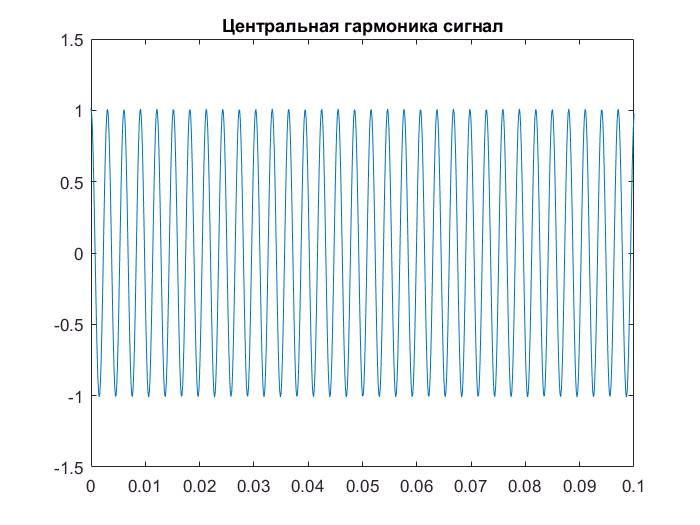

title('Центральная гармоника сигнал');

sound(repmat(real(z), 1, 10), fs);